# Correlation Analysis 

## Data preparation

Our dataset is formed by data from 2010 to 2020. We have chosen three subsets of data: dataset for 2018, 2017 and 2016  to apply correlation Analysis so that, we contrast results obtained for different years. These three dataset have passed cleaning process and the % of rejected rows has been so low.

## Correlation Analysis

## 1 Annual Correlation Analysis

data2018 = data10_Real_clean(data10_Real_clean.YY == 2018,:)

data2018 = 8587×15 table
     YY     MM    DD    hh    mm    WDIR    WSPD    GST    WVHT     DPD     APD     MWD     PRES     ATMP    WTMP
    ____    __    __    __    __    ____    ____    ___    ____    _____    ____    ___    ______    ____    ____

    2018    1     1      0    50     36     0.8     1.4    0.85    10.81    7.65    274    1019.3    13.4    13.9
    2018    1     1      1    50     17     0.8     1.1    0.92    10.81    7.99    273    1019.9    13.4    13.9
    2018

data2017 = data10_Real_clean(data10_Real_clean.YY == 2017,:)

data2017 = 8416×15 table
     YY     MM    DD    hh    mm    WDIR    WSPD    GST    WVHT     DPD     APD     MWD     PRES     ATMP    WTMP
    ____    __    __    __    __    ____    ____    ___    ____    _____    ____    ___    ______    ____    ____

    2017    1     1      0    50    322     1.5     2.5    2.52    10.81    8.67    305      1013    11.1    12.9
    2017    1     1      1    50     36     6.5     8.2    2.22     12.9    8.45    303    1013.2    10.5    12.9
    2017

data2016 = data10_Real_clean(data10_Real_clean.YY == 2016,:)

data2016 = 8531×15 table
     YY     MM    DD    hh    mm    WDIR    WSPD    GST    WVHT     DPD     APD     MWD     PRES     ATMP    WTMP
    ____    __    __    __    __    ____    ____    ___    ____    _____    ____    ___    ______    ____    ____

    2016    1     1      0    50    314     3.6     4.8    1.42    11.43    8.48    308    1019.8    12.5    14.9
    2016    1     1      1    50    311     3.6     4.6    1.45    11.43    8.66    304    1019.9    12.3    14.8
    2016

**Pearson's Linear correlation coefficient of Wind speed with rest of variables**

%R2018_YY =  corrcoef(data2018.WSPD, data2018.YY); -> It not make sense
%because we are evaluating just one year
R2018_mm =  corrcoef(data2018.WSPD, data2018.mm); %mm -> is always 50
data2018 = removevars(data2018, 'YY');
data2018 = removevars(data2018, 'mm');
R2018 =  corrcoef(table2array(data2018))

R2018 =     1.0000    0.0079   -0.0040    0.0198    0.0046    0.0070   -0.0434   -0.0255   -0.0725   -0.1357   -0.2633    0.5597    0.6003
    0.0079    1.0000    0.0024    0.0771    0.0626    0.0693    0.1032    0.1041    0.0319    0.0116    0.1301   -0.0538   -0.0053
   -0.0040    0.0024    1.0000   -0.0718   -0.0529   -0.0539   -0.0131    0.0108    0.0444   -0.0170    0.0642   -0.0387    0.0127
    0.0198    0.0771   -0.0718    1.0000    0.3782    0.3762    0.0949   -0.1214   -0.2850    0.0075   -0.1360    0.0032   -0.0272
    0.0046    0.0626   -0.0529    0.3782    1.0000    0.9951    0.4425   -0.2281   -0.4823    0.1473   -0.0972   -0.1025   -0.1894
    0.0070    0.0693   -0.0539    0.3762    0.9951    1.0000    0.4658   -0.2264   -0.4662    0.1520   -0.1042   -0.1142   -0.1919
   -0.0434    0.1032   -0.0131    0.0949    0.4425    0.4658    1.0000    0.0584    0.3284    0.3576    0.1459   -0.2296   -0.2464
   -0.0255    0.1041    0.0108   -0.1214   -0.2281   -0.2264    0.0584    1

**Year 2017**

data2017 = removevars(data2017, 'YY');
data2017 = removevars(data2017, 'mm');
R2017 =  corrcoef(table2array(data2017))

R2017 =     1.0000    0.0404    0.0020    0.0633   -0.1552   -0.1634   -0.1922    0.0161    0.0585    0.0393   -0.1651    0.6380    0.6486
    0.0404    1.0000    0.0021    0.0842    0.0239    0.0255    0.0379   -0.0272    0.0003    0.1155    0.0357   -0.0101    0.0252
    0.0020    0.0021    1.0000   -0.0508   -0.0449   -0.0469   -0.0351    0.0010    0.0147   -0.0322    0.0706   -0.0202    0.0111
    0.0633    0.0842   -0.0508    1.0000    0.3476    0.3429    0.0486   -0.1604   -0.3280    0.0302   -0.2093    0.0420   -0.0003
   -0.1552    0.0239   -0.0449    0.3476    1.0000    0.9952    0.4344   -0.2567   -0.5075    0.1603   -0.0933   -0.1682   -0.2597
   -0.1634    0.0255   -0.0469    0.3429    0.9952    1.0000    0.4590   -0.2521   -0.4896    0.1632   -0.1043   -0.1845   -0.2682
   -0.1922    0.0379   -0.0351    0.0486    0.4344    0.4590    1.0000    0.0739    0.2927    0.3013   -0.0702   -0.2824   -0.3355
    0.0161   -0.0272    0.0010   -0.1604   -0.2567   -0.2521    0.0739    1

**Year 2016**

data2016 = removevars(data2016, 'YY');
data2016 = removevars(data2016, 'mm');
R2016 =  corrcoef(table2array(data2016))

R2016 =     1.0000   -0.0019   -0.0028   -0.0206   -0.0631   -0.0708   -0.2264   -0.1280   -0.1865   -0.0202   -0.1518    0.2444    0.3553
   -0.0019    1.0000    0.0006    0.0397    0.1146    0.1158    0.0929   -0.0032   -0.0378    0.0139   -0.0216   -0.0223   -0.0835
   -0.0028    0.0006    1.0000   -0.0401   -0.0315   -0.0340   -0.0213    0.0091    0.0151   -0.0223    0.0687   -0.0131    0.0151
   -0.0206    0.0397   -0.0401    1.0000    0.3462    0.3482    0.0193   -0.1569   -0.2748   -0.0332   -0.1459    0.0462    0.0149
   -0.0631    0.1146   -0.0315    0.3462    1.0000    0.9947    0.3939   -0.1985   -0.4467    0.1437   -0.0949   -0.0897   -0.2544
   -0.0708    0.1158   -0.0340    0.3482    0.9947    1.0000    0.4217   -0.1950   -0.4281    0.1477   -0.1057   -0.1071   -0.2566
   -0.2264    0.0929   -0.0213    0.0193    0.3939    0.4217    1.0000    0.2257    0.4194    0.2537    0.1297   -0.1638   -0.2740
   -0.1280   -0.0032    0.0091   -0.1569   -0.1985   -0.1950    0.2257    1

## **Pearson correlation coefficient**

This parametric correlation is equivalent to Spearman correlation analysis when the amount of data is huge enough. Let's probe it

When we have calculated Spearman correlation we save also the p values that measures the risk of reject the hypothesis of no correlation hypothesis (null hypothesis). Small p-values less than  5% (P<0.05) means that you can reject the null hypothesis, small risk of not considering no correlation (at least linear)

[S2018,PVAL_2018] = corr(table2array(data2018),'Type','Spearman')

S2018 =     1.0000    0.0079   -0.0040    0.0206    0.0089    0.0121   -0.0383   -0.0305   -0.0737   -0.1290   -0.2680    0.5637    0.6139
    0.0079    1.0000    0.0024    0.0873    0.0663    0.0743    0.0928    0.1034    0.0475    0.0330    0.1222   -0.0485   -0.0191
   -0.0040    0.0024    1.0000   -0.1659   -0.0533   -0.0548   -0.0093    0.0102    0.0481   -0.0311    0.0684   -0.0375    0.0126
    0.0206    0.0873   -0.1659    1.0000    0.3270    0.3292    0.1785   -0.0903   -0.1950    0.0907   -0.0108   -0.0451   -0.0572
    0.0089    0.0663   -0.0533    0.3270    1.0000    0.9957    0.4601   -0.2342   -0.5316    0.1879   -0.1198   -0.1003   -0.1841
    0.0121    0.0743   -0.0548    0.3292    0.9957    1.0000    0.4798   -0.2316   -0.5209    0.1935   -0.1247   -0.1103   -0.1854
   -0.0383    0.0928   -0.0093    0.1785    0.4601    0.4798    1.0000   -0.0196    0.2483    0.3485    0.0717   -0.2350   -0.2778
   -0.0305    0.1034    0.0102   -0.0903   -0.2342   -0.2316   -0.0196    1

PVAL_2018 =     1.0000    0.4651    0.7091    0.0564    0.4104    0.2623    0.0004    0.0047    0.0000    0.0000    0.0000         0         0
    0.4651    1.0000    0.8254    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0022    0.0000    0.0000    0.0763
    0.7091    0.8254    1.0000    0.0000    0.0000    0.0000    0.3887    0.3424    0.0000    0.0040    0.0000    0.0005    0.2424
    0.0564    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.3154    0.0000    0.0000
    0.4104    0.0000    0.0000    0.0000    1.0000         0         0    0.0000         0    0.0000    0.0000    0.0000    0.0000
    0.2623    0.0000    0.0000    0.0000         0    1.0000         0    0.0000         0    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000    0.3887    0.0000         0         0    1.0000    0.0699    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0047    0.0000    0.3424    0.0000    0.0000    0.0000    0.0699 

[S2017,PVAL_2017] = corr(table2array(data2017),'Type','Spearman')

S2017 =     1.0000    0.0403    0.0020    0.0281   -0.1502   -0.1571   -0.2148    0.0107    0.0590    0.1367   -0.1744    0.6682    0.6959
    0.0403    1.0000    0.0020    0.0998    0.0194    0.0205    0.0120   -0.0374   -0.0092    0.0694    0.0248    0.0075    0.0370
    0.0020    0.0020    1.0000   -0.1116   -0.0441   -0.0464   -0.0277    0.0008    0.0233   -0.0529    0.0739   -0.0173    0.0116
    0.0281    0.0998   -0.1116    1.0000    0.3489    0.3482    0.1326   -0.1137   -0.2772    0.1403   -0.0572   -0.0590   -0.0901
   -0.1502    0.0194   -0.0441    0.3489    1.0000    0.9958    0.4475   -0.2539   -0.5471    0.2282   -0.0849   -0.1569   -0.2495
   -0.1571    0.0205   -0.0464    0.3482    0.9958    1.0000    0.4642   -0.2489   -0.5352    0.2302   -0.0936   -0.1725   -0.2560
   -0.2148    0.0120   -0.0277    0.1326    0.4475    0.4642    1.0000    0.0021    0.2259    0.2970   -0.0230   -0.2946   -0.3583
    0.0107   -0.0374    0.0008   -0.1137   -0.2539   -0.2489    0.0021    1

PVAL_2017 =     1.0000    0.0002    0.8546    0.0099    0.0000    0.0000    0.0000    0.3284    0.0000    0.0000    0.0000         0         0
    0.0002    1.0000    0.8554    0.0000    0.0753    0.0599    0.2729    0.0006    0.4007    0.0000    0.0230    0.4943    0.0007
    0.8546    0.8554    1.0000    0.0000    0.0001    0.0000    0.0110    0.9419    0.0329    0.0000    0.0000    0.1124    0.2891
    0.0099    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0753    0.0001    0.0000    1.0000         0         0    0.0000         0    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0599    0.0000    0.0000         0    1.0000         0    0.0000         0    0.0000    0.0000    0.0000    0.0000
    0.0000    0.2729    0.0110    0.0000         0         0    1.0000    0.8468    0.0000    0.0000    0.0345    0.0000    0.0000
    0.3284    0.0006    0.9419    0.0000    0.0000    0.0000    0.8468 

[S2016,PVAL_2016] = corr(table2array(data2016),'Type','Spearman')

S2016 =     1.0000   -0.0019   -0.0028   -0.0001   -0.0518   -0.0572   -0.1873   -0.1227   -0.1683    0.0513   -0.1478    0.2501    0.3412
   -0.0019    1.0000    0.0006    0.0299    0.1115    0.1123    0.1165   -0.0017   -0.0504    0.0399   -0.0273   -0.0371   -0.0768
   -0.0028    0.0006    1.0000   -0.1225   -0.0318   -0.0343   -0.0186    0.0090    0.0195   -0.0401    0.0718   -0.0149    0.0126
   -0.0001    0.0299   -0.1225    1.0000    0.3273    0.3298    0.0400   -0.1108   -0.2555    0.0755   -0.0118   -0.0046   -0.0293
   -0.0518    0.1115   -0.0318    0.3273    1.0000    0.9950    0.3667   -0.1911   -0.4873    0.1922   -0.0595   -0.0603   -0.2242
   -0.0572    0.1123   -0.0343    0.3298    0.9950    1.0000    0.3884   -0.1875   -0.4741    0.1915   -0.0668   -0.0756   -0.2221
   -0.1873    0.1165   -0.0186    0.0400    0.3667    0.3884    1.0000    0.1771    0.3707    0.1474    0.1578   -0.1533   -0.2575
   -0.1227   -0.0017    0.0090   -0.1108   -0.1911   -0.1875    0.1771    1

PVAL_2016 =     1.0000    0.8610    0.7937    0.9893    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.8610    1.0000    0.9532    0.0058    0.0000    0.0000    0.0000    0.8781    0.0000    0.0002    0.0116    0.0006    0.0000
    0.7937    0.9532    1.0000    0.0000    0.0033    0.0016    0.0851    0.4062    0.0722    0.0002    0.0000    0.1675    0.2461
    0.9893    0.0058    0.0000    1.0000    0.0000    0.0000    0.0002    0.0000    0.0000    0.0000    0.2763    0.6719    0.0068
    0.0000    0.0000    0.0033    0.0000    1.0000         0    0.0000    0.0000         0    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0016    0.0000         0    1.0000    0.0000    0.0000         0    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0851    0.0002    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.8781    0.4062    0.0000    0.0000    0.0000    0.0000 

## **Total data set correlation analysis**

RTotal10_Real =  corrcoef(table2array(data10_Real_clean))

RTotal10_Real =     1.0000   -0.0722   -0.0057   -0.0011   -0.2227   -0.0272    0.0172    0.0252   -0.0045    0.0429    0.0300   -0.0824   -0.0159    0.2183    0.2788
   -0.0722    1.0000    0.0157   -0.0001   -0.2122   -0.0044   -0.0784   -0.0790   -0.1495   -0.0757   -0.0781   -0.0217   -0.1684    0.4496    0.5180
   -0.0057    0.0157    1.0000   -0.0001   -0.0183    0.0244    0.0395    0.0408    0.0249   -0.0091   -0.0137    0.0502    0.0133   -0.0092   -0.0124
   -0.0011   -0.0001   -0.0001    1.0000   -0.0007   -0.0524   -0.0425   -0.0440   -0.0210    0.0135    0.0240   -0.0255    0.0577   -0.0104    0.0103
   -0.2227   -0.2122   -0.0183   -0.0007    1.0000    0.0484    0.0142   -0.0025   -0.0181   -0.0409   -0.0353    0.0016    0.0012   -0.0442   -0.0923
   -0.0272   -0.0044    0.0244   -0.0524    0.0484    1.0000    0.3602    0.3540    0.0383   -0.1340   -0.2836    0.0358   -0.1221    0.0696    0.0198
    0.0172   -0.0784    0.0395   -0.0425    0.0142    0.3602    1.0000    0.99

[STotal10_Real,PVAL_Total10_Real] = corr(table2array(data10_Real_clean),'Type','Spearman')

STotal10_Real =     1.0000   -0.0806   -0.0067   -0.0011   -0.2365   -0.0934    0.0147    0.0224   -0.0123    0.0438    0.0309   -0.0547   -0.0046    0.2107    0.2734
   -0.0806    1.0000    0.0153   -0.0000   -0.2093    0.0238   -0.0697   -0.0694   -0.1560   -0.0859   -0.0767    0.0260   -0.1843    0.4509    0.5349
   -0.0067    0.0153    1.0000   -0.0001   -0.0182    0.0325    0.0393    0.0411    0.0264   -0.0082   -0.0177    0.0361    0.0109   -0.0082   -0.0162
   -0.0011   -0.0000   -0.0001    1.0000    0.0001   -0.1282   -0.0435   -0.0451   -0.0182    0.0129    0.0290   -0.0470    0.0620   -0.0099    0.0109
   -0.2365   -0.2093   -0.0182    0.0001    1.0000    0.0300    0.0160    0.0001   -0.0125   -0.0452   -0.0401    0.0441   -0.0197   -0.0622   -0.1227
   -0.0934    0.0238    0.0325   -0.1282    0.0300    1.0000    0.3362    0.3336    0.0820   -0.1067   -0.2479    0.1412   -0.0043   -0.0093   -0.0375
    0.0147   -0.0697    0.0393   -0.0435    0.0160    0.3362    1.0000    0.99

PVAL_Total10_Real =     1.0000    0.0000    0.0769    0.7712         0    0.0000    0.0001    0.0000    0.0012    0.0000    0.0000    0.0000    0.2221         0         0
    0.0000    1.0000    0.0001    0.9929         0    0.0000    0.0000    0.0000         0    0.0000    0.0000    0.0000         0         0         0
    0.0769    0.0001    1.0000    0.9778    0.0000    0.0000    0.0000    0.0000    0.0000    0.0315    0.0000    0.0000    0.0040    0.0310    0.0000
    0.7712    0.9929    0.9778    1.0000    0.9687    0.0000    0.0000    0.0000    0.0000    0.0007    0.0000    0.0000    0.0000    0.0090    0.0043
         0         0    0.0000    0.9687    1.0000    0.0000    0.0000    0.9754    0.0010    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    1.0000         0         0    0.0000    0.0000         0    0.0000    0.2536    0.0139    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000         0    1.0000    

## **Correlation analysis plots**

Firstly we calculate the central measures, including the average of the variable

Average values are so similar from one year to another

cm_WSPD2018 = centralMeasures(data2018.WSPD,2018)

cm_WSPD2018 = struct with fields:
        year: 2018
        mean: 6.0450
      median: 6
        mode: 6.4000
    trimmean: 5.9772
     geomean: NaN
    harmmean: NaN


cm_WSPD2017 = centralMeasures(data2018.WSPD,2017)

cm_WSPD2017 = struct with fields:
        year: 2017
        mean: 6.0450
      median: 6
        mode: 6.4000
    trimmean: 5.9772
     geomean: NaN
    harmmean: NaN


cm_WSPD2016 = centralMeasures(data2016.WSPD,2016)

cm_WSPD2016 = struct with fields:
        year: 2016
        mean: 5.7644
      median: 5.5000
        mode: 3.5000
    trimmean: 5.6300
     geomean: NaN
    harmmean: NaN


cm_WVHT2018 = centralMeasures(data2018.WVHT,2018)

cm_WVHT2018 = struct with fields:
        year: 2018
        mean: 1.9779
      median: 1.8700
        mode: 1.6700
    trimmean: 1.9060
     geomean: 1.8460
    harmmean: 1.7226


cm_WVHT2017 = centralMeasures(data2018.WVHT,2017)

cm_WVHT2017 = struct with fields:
        year: 2017
        mean: 1.9779
      median: 1.8700
        mode: 1.6700
    trimmean: 1.9060
     geomean: 1.8460
    harmmean: 1.7226


cm_WVHT2016 = centralMeasures(data2016.WVHT,2016)

cm_WVHT2016 = struct with fields:
        year: 2016
        mean: 2.2043
      median: 2.0100
        mode: 1.5700
    trimmean: 2.1188
     geomean: 2.0551
    harmmean: 1.9204


### Point clouds with lines for average values

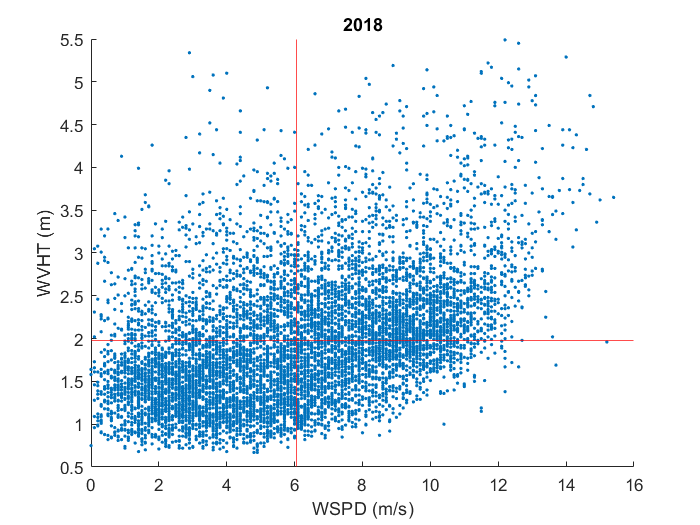

clf
hold on
plot(data2018.WSPD, data2018.WVHT, '.')
xline(cm_WSPD2018.mean,'red');
yline(cm_WVHT2018.mean, 'red');
title("2018");
xlabel("WSPD (m/s)");
ylabel("WVHT (m)")
hold off

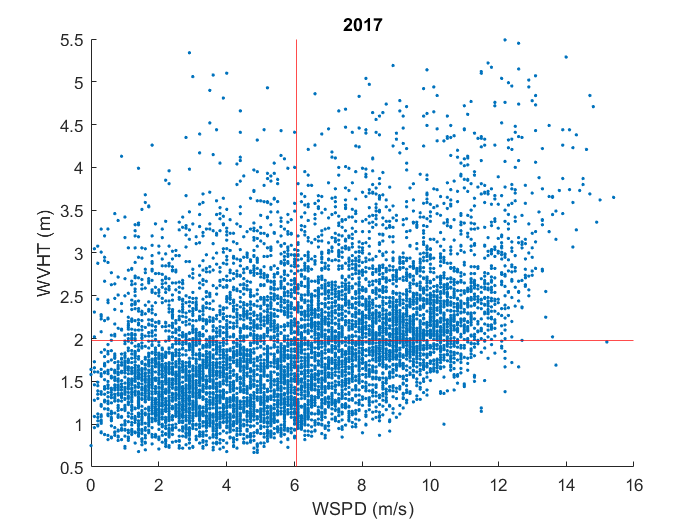

clf
hold on
plot(data2018.WSPD, data2018.WVHT, '.')
xline(cm_WSPD2017.mean,'red');
yline(cm_WVHT2017.mean, 'red');
title("2017")
xlabel("WSPD (m/s)");
ylabel("WVHT (m)")
hold off

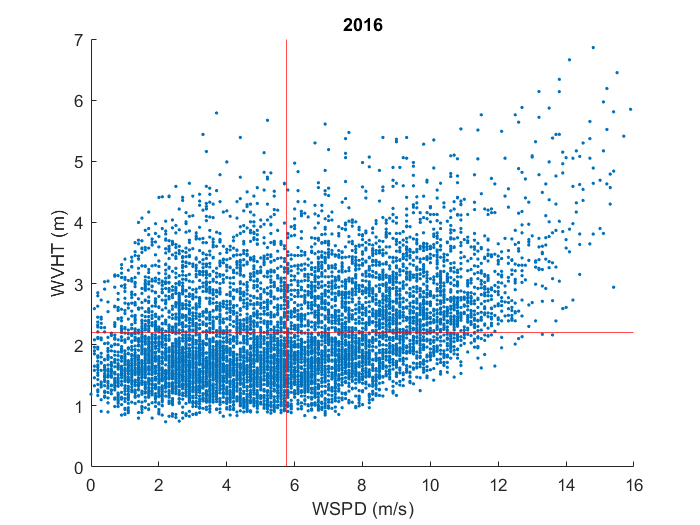

clf
hold on
plot(data2016.WSPD, data2016.WVHT, '.')
xline(cm_WSPD2016.mean,'red');
yline(cm_WVHT2016.mean, 'red');
title("2016")
xlabel("WSPD (m/s)");
ylabel("WVHT (m)")
hold off

The points clouds for each of the years are very similar and the possible correlation between variables seems to be direct correlation.

As originally stated, Spearman and Pearson correlation analysis gives similar results